# Numerical Analysis Take-Home Final, Fall 2019

## Maxwell Greene

## Problem #1

X = [1;1]; Tol=.001; df=20; ak = 1.0;
funcs = @(x,y) [3*x^2-x*y^2+x^2*y-13; x*y-2*x^2+y^2-4];

while df > Tol
    Xn = X-ak*InvJac(X)*funcs(X(1),X(2));
    df =(dot((Xn-X),(Xn-X)))^0.5; 
    X = Xn;
end
X'

ans =     2.3502    2.8780


## Problem #2

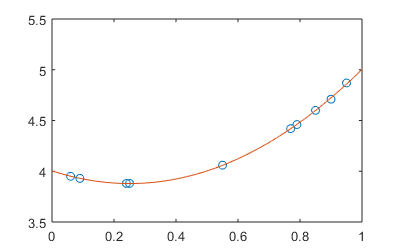

%Creating data
xVals = [0.90,0.95,0.77,0.79,0.25,0.55,0.09,0.85,0.24,0.06];
b = [4.71,4.87,4.42,4.46,3.88,4.06,3.93,4.60,3.88,3.95]';
A = [ones(10,1), xVals',xVals.^2']; 
x = 0:.01:1;
a = linsolve(A,b);
p = plot(xVals,b,'o',x,a(1)+a(2)*x+a(3)*x.^2);
k = p.Parent; k.Parent.Position = [100 100 400 250]; 

a'

ans =     4.0043   -1.0028    2.0023


## Problem #5

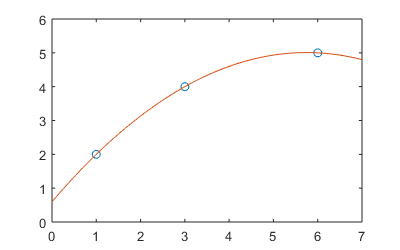

xVals = [1,3,6]; 
yVals = [2,4,5];
x = linspace(0,7,101);
y = ppval(spline(xVals,yVals),x);
plot(xVals,yVals,'o',x,y);

## Problem #8

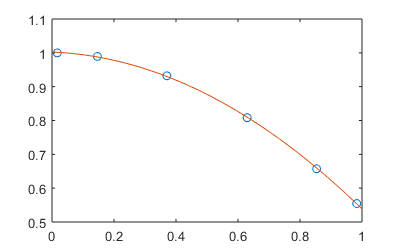

n = 6; np = 2; 
a = 0; b = 1; i = 0:1:n;
t = a + (b-a)/2*(cos((2*i-1)*pi/(2*n))+1); f = cos(t);
[p,S, mu] = polyfit(t,f,np);
x = linspace(a,b,101); 
fp = polyval(p,x,S,mu);
plot(t,f, 'o', x, fp)

## Problem #9

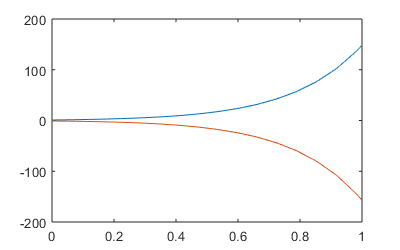

y0 = [1, -1]; 
tspan = [0,1];
[t,y] = ode23(@(t,y)odefcn9(t,y), tspan, y0);
plot(t, y(:,1), t, y(:,2))

## Problem #10

A = [8,6,2,1,0,0,0,120;
    4,2,1,0,1,0,0,86;
    4,2,2,0,0,1,0,160;
    -2,-1.8,-0.85,0,0,0,1,0];
nr = size(A, 1); nc = size(A, 2);

for j = 1:nc-1
    [M, I] = min(A(nr,:));
    for i = 1:nr-1
        PC(i) = A(i,I);
    end
    for i = 1:nr-1
        LC(i) = A(i,nc);
    end
    Ratio = LC'./PC';
    for k = 1:nr-1
        if(Ratio(k) < 0) Ratio(k) = 1e99; end
    end
    [PivPoint, IP]  = min(Ratio);
    A(IP,:) = A(IP,:)/A(IP, I);
    for i = 1:nr
        if i ~= IP
            A(i,:)  =-A(i,I)*A(IP, :) + A(i,:);
        end
    end
end
A

A =     4.0000    3.0000    1.0000    0.5000         0         0         0   60.0000
         0   -1.0000         0   -0.5000    1.0000         0         0   26.0000
   -4.0000   -4.0000         0   -1.0000         0    1.0000         0   40.0000
    1.4000    0.7500         0    0.4250         0         0    1.0000   51.0000


A(length(A(:,1)),length(A))

ans = 51

## Problem #11

tx = [0:.1111:1];
yx = [-0.0148;0.0714;0.0999;0.1099;0.1342;0.1399;0.1448;0.1417;0.1664;0.1679];
optFunc = @(input) errorFunction(input(1),input(2),tx,yx);
optVals = optimize(optFunc,[0,0])

optVals =     8.2989    0.4248


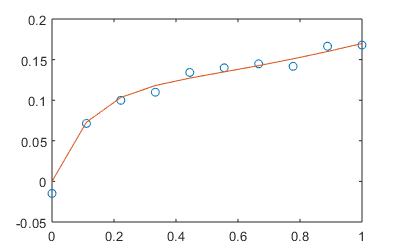

a = optVals(1); 
b = optVals(2);
[t,y] = ode23s(@(t,y) odefunc11(t,y,a,b),tx,[0,1]);
plot(tx,yx,'o',t,y(:,1));

## Functions used in questions:

Problem #1

function InvJ = InvJac(X)
    x = X(1); y = X(2);
    J = [6*x-y^2+2*x*y,-2*x*y+x^2;y-4*x,x+2*y];
    InvJ = inv(J);
end

Problem #9

function dydt = odefcn9(~, y)
    dydt = [3*y(1)^(1/2) - 4*y(2)
                 -8*y(1) - 3*y(2)]; 
end

Problem #11

function dydt = odefunc11(t,z,c,d)
    dydt = [z(2);-c*z(2)+z(1)+t*exp(-d*t)];
end

function [a,b] = optimize(optfunc,params)
    [a,b] = fminsearch(optfunc,[params(1),params(2)]);
end

function error = errorFunction(a1,a2,tx,yx)
    [~,y] = ode23s(@(t,y) odefunc11(t,y,a1,a2),tx,[0,1]);
    error = sum((y(:,1)-yx).^2);
end